# Primer parcial

## Señales básicas

### 1.-

Suponga que $x(t)=tcos(2\pi t)$ con $0\leq t \leq5$.

Graficar:

- 
$$x(t)$$


- 
$$x(-t)
$$


- 
$$x(t/5)$$


- 
$$x(1+3t)$$


- 
$$x(-1-3t)$$


Debe hacerse una señal continua y una discreta. El resultado debe tener leyenda, tal como se muestra a continuación.

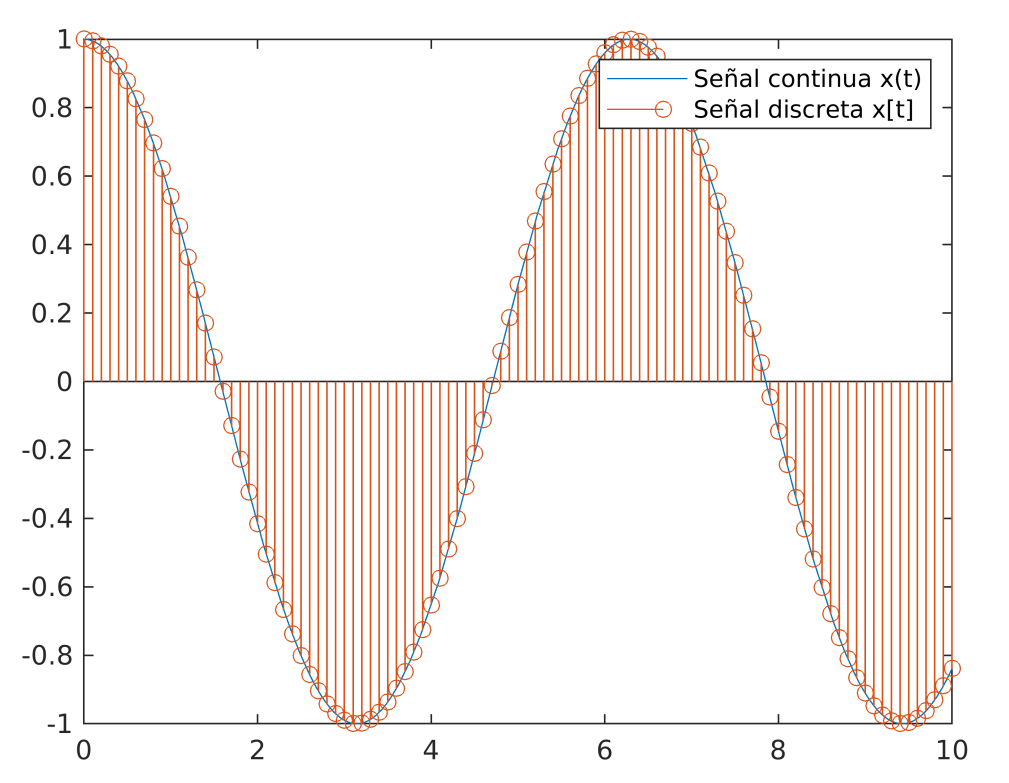

## **Importación de datasets**

### 2.-

Importar los siguientes archivos desde Utils4SP:

- **Sonda_Ace.txt **: Se necesita la herramienta de importación manual. Debe salir una tabla, en donde los nombre de los campos describan el parámetro físico medido, sus unidades y el tipo de variable. Son ~329k lecturas 

            

            Una vez que el resultado sea satisfactorio, exportar la función con un nombre similar a "importfile_sondaAce.m"

- **ruido.wav: **Debe salir una matriz con las muestras del audio y una variable con la frecuencia de muestreo.

- **IrishNationalTideGauge.csv: **Debe salir una tabla con ~250k lecturas. 

En todos los casos, los datos deben estar disponibles en el Worskpace. Dejar la salida de las funciones habilitadas para ver el resultado.

## Lectura de archivo .mat

Limpiar el workspace e importar el archivo .mat "E1_PrimerParcial.mat". Incluye los datos anteriores con un poco de preprocesamiento. Será necesario para las siguientes secciones.

## Plots exploratorios

### 3.-

Obtener las siguientes gráficas para los datos de la sonda Ace.

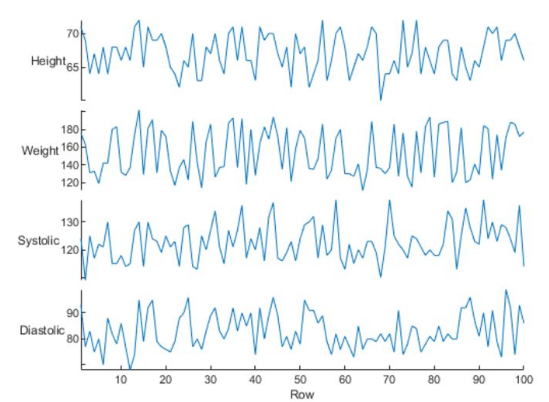  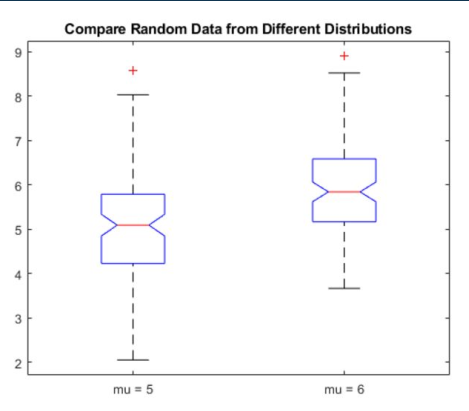 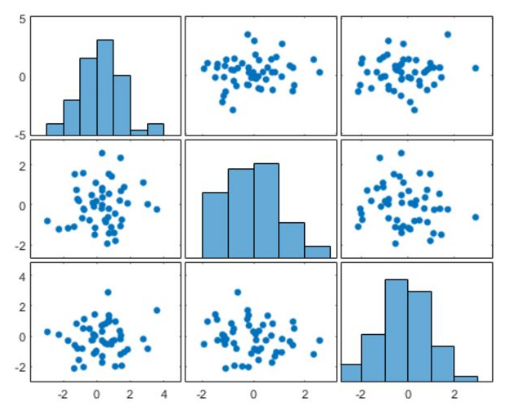

### 4.-

Obtener las siguientes visualizaciones para la variable "Water_Level_OD_Malin" de la tabla "IrishTide".

Nota: Estas visualizaciones estarán bien ejecutadas pero su resultado será insatisfactorio.

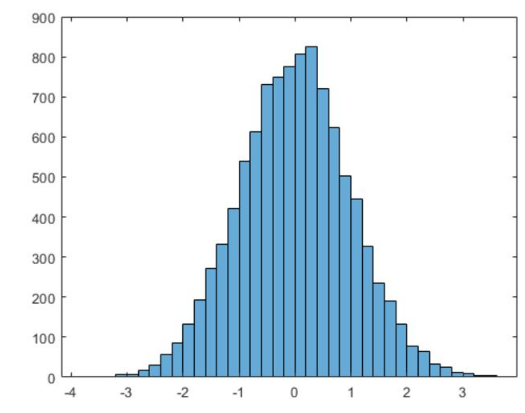 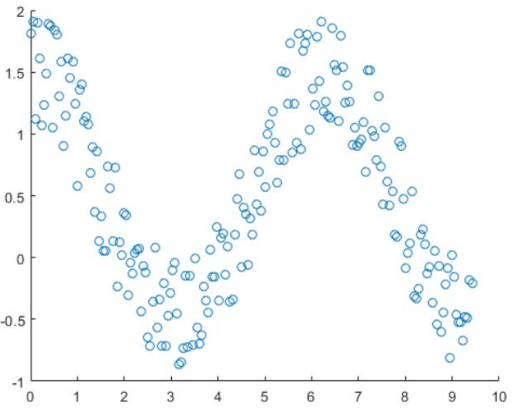

## Preprocesamiento 

### 5.-

Diagnosticar el número de NaN's en los datos de la Sonda Ace y de Irish Tide. Una vez diagnosticado, removerlos y probar que ya no hay NaN's.

Nota: ¡No hay que sobre escribir variables!

Una vez removidos los Nans, obtener la siguiente vizualización de IrishTides:

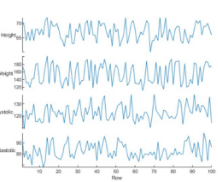

¿Los resultados ya son satisfactorios? Discute el por qué sí o por qué no.

### 7.-

Elegir una porción de datos entre el 6 de Mayo del 2020 a las 6 am y la última lectura disponible en IrishTide. Con esos datos, hacer las siguientes visualizaciones. Incluir títulos y ejes.

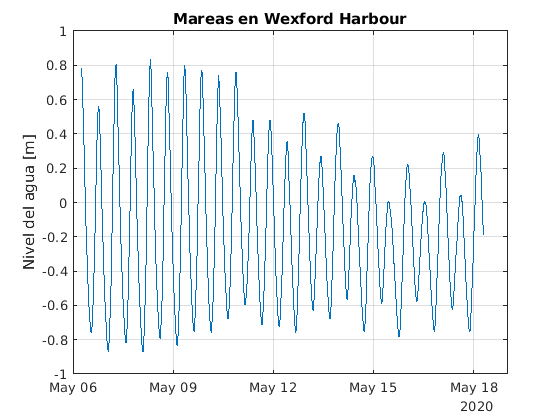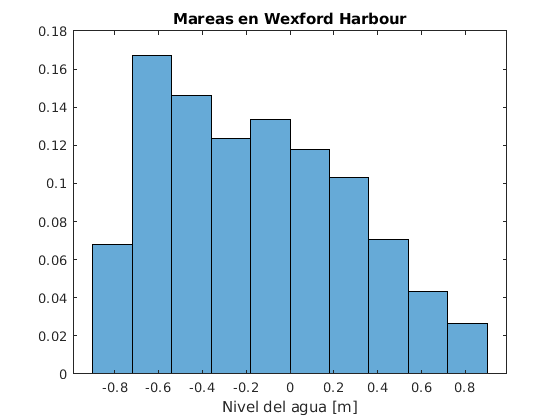

## Estadística 101

### 8.-

Obtener el la mediana, promedio, primer cuartil y tercer cuartil para los datos de IrishTide entre el 6 de Mayo del 2020 a las 6am y la última lectura  disponible. Dibujar las líneas de estas cantidades sobre el histograma y la serie de tiempo.

### 9.-

De la siguiente figura, discute por qué el valor del promedio y de la mediana difieren. 

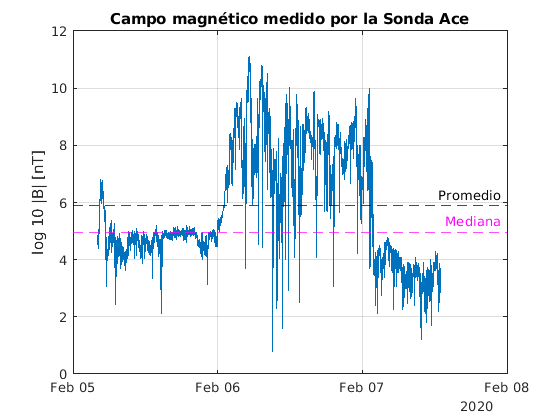

### 10.-

- Hacer una serie de tiempo e histograma de *ruido*. 

- Poner con una línea el promedio y sus desviaciones a 1 y 2 $\sigma$sobre la serie de tiempo y el histograma.

### 11.-

- Ajustar una función gaussiana (Usar "gauss1" en lugar de "poly1" ) a la distribución de datos de ruido. 

- Mostrar el valor de $r^2$ y discutir si es un buen ajuste o no.

- Plotear el ajuste encima del histograma.

- Después de ver el ajuste y el valor de $r^2$, ¿Consideras que el ajuste es bueno?

El resultado final debe verse así:

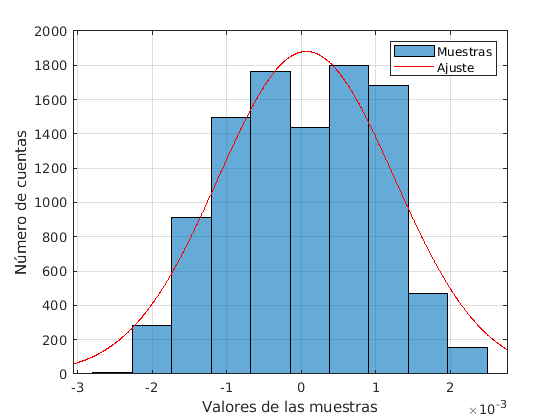

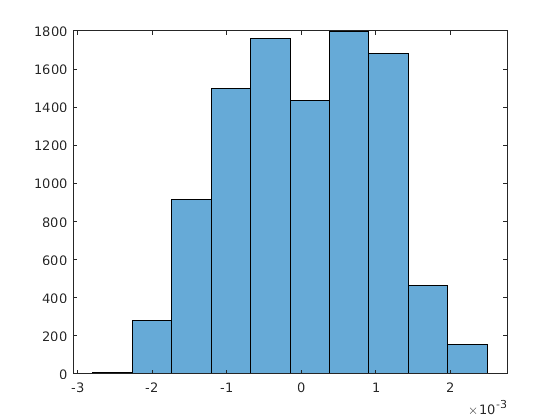

%Usar esta línea de código antes de hacer el ajuste.

%Extraerá las cantidades necesarias par usar la función de ajustes.
h=histogram(ruido,10);
y=h.BinCounts';
x=h.BinEdges+h.BinWidth/2;
x=x(1:end-1)';
